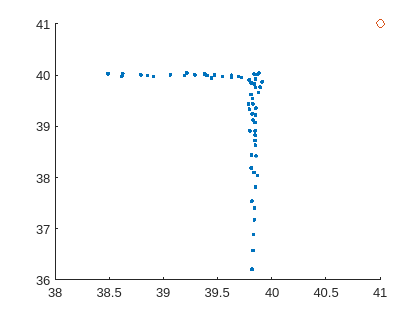

id = 1;
pos = [41;41];
rad = 5;
[b,a]=lidar_sim(obstacles,pos,rad,360);
a(1,:) = a(1,:) + 0.05*randn(1,length(a));
a(2,:) = a(2,:);
a(2,:) =adjust_angle(a(2,:));

figure
hold on 
plot(pos(1)+a(1,:).*cos(a(2,:)),pos(2)+a(1,:).*sin(a(2,:)),'.')
plot(pos(1),pos(2),'o')

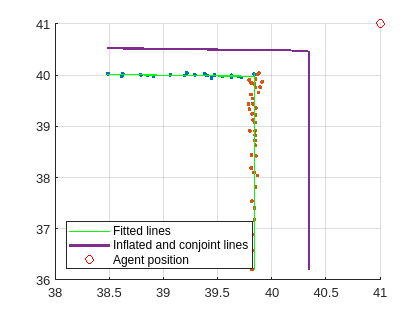


K=regr_scan(a,pos,0.25);
[~, KK] = inflate(K,0,pos);
[~, KR] = inflate(K,0.5,pos);
figure
hold on 
grid on
%axis equal
for i=1:length(K)
plot(K{i}(1,:),K{i}(2,:),'.')
end
plot(KK(1,:),KK(2,:),'LineWidth',1,'Color','g')
plot(KR(1,:),KR(2,:),'LineWidth',2)
plot(pos(1),pos(2),'or')
legend('','','Fitted lines','Inflated and conjoint lines','Agent position','Position',[0 0 1 2],'Location','southwest')

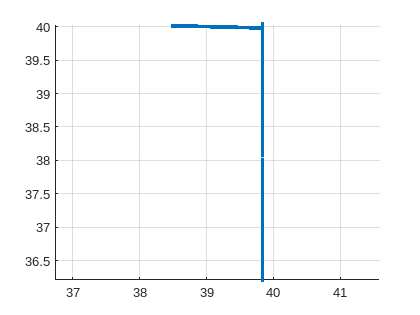





figure
hold on 
grid on
axis equal
plot(KK(1,:),KK(2,:),'.')

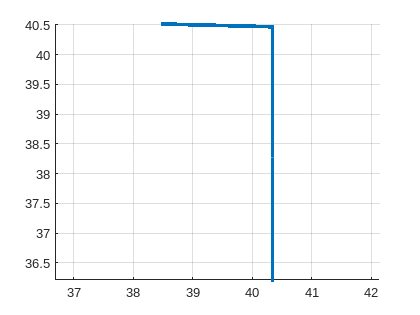

figure
hold on 
grid on
axis equal
plot(KR(1,:),KR(2,:),'.')

% plot(K{1}(1,:),K{1}(2,:),'.')
% plot(K{2}(1,:),K{2}(2,:),'.')
% 
% figure
% plot(k_int(1,:),k_int(2,:),'.')
bots(id).pos=[52;22;0];
bots(id).pos_est=[52;22;0]
bots=update_obstacles(obstacles,bots,n_lidar);
[c,b]=bots(id).vertex_unc2;

Output argument "inf" (and possibly others) not assigned a value in the execution with "DiffBot/vertex_unc2" function.

figure
hold on
bots(id).plot_bot
plot(bots(id).pos_est(1)+bots(id).obsts_lidar(1,:).*cos(bots(id).obsts_lidar(2,:)),bots(id).pos_est(2)+ bots(id).obsts_lidar(1,:).*sin(bots(id).obsts_lidar(2,:)),'.')
plot(bots(id).pos_est(1)+c(1,:).*cos(c(2,:)),bots(id).pos_est(2)+ c(1,:).*sin(c(2,:)),'.')
plot(bots(id).pos_est(1)+b(1,:).*cos(b(2,:)),bots(id).pos_est(2)+ b(1,:).*sin(b(2,:)),'.')


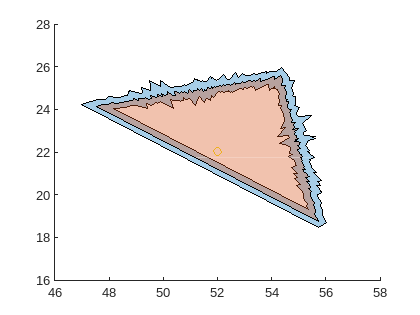

b=polar2cartesian(a,pos);
c=polyshape(b');
poly = polybuffer(b','lines',0.25,'JointType','miter');
figure
hold on
plot(poly)
plot(c)
plot(pos(1),pos(2),'o')

id =7;
xc=bots(id).pos_est(1,1)-0.5;

Index exceeds the number of array elements. Index must not exceed 5.

yc=bots(id).pos_est(2,1);


% 
% figure 
% hold on
% bots(id).plot_bot

%bots(2).steps_vert = 101;

rad = 4
%%bots(2).rs=30/2.2;
%update_obstacles(obstacles,bots,n_lidar);
%pp=bots(2).vertex_unc2
[b,a]=lidar_sim(obstacles,[xc;yc],rad,360);

a(1,:)=a(1,:)+1*0.05*randn(1,size(a,2));
a(2,:)=a(2,:)+0*bots(id).pos(3);
a(2,:) = adjust_angle(a(2,:));

figure 
hold on
bots(id).plot_bot
plot(bots(id).verts_zi(1,:),bots(id).verts_zi(2,:),'.')
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')
update_obstacles(obstacles,bots,n_lidar);

bots(id).vertex_unc2
figure 
axis equal
hold on
plot(xc,yc,'o',MarkerSize=10)
%plot(a(1,:).*cos(a(2,:)),a(1,:).*sin(a(2,:)),'.')

obst = regr_scan(a,[xc;yc],0.2);
obst = inflate(obst,bots(id).uncertainty_calc+bots(id).bot_dim+3.*0.02,bots(id).pos);
bots(id).plot_bot

for i=1:length(obst)
plot(obst{i}(1,:),obst{i}(2,:),'.')
end
